## PSO 

Particle Swarm Optimization


$$\mathrm{particula}\;i\to {\vec{x} }_i \;\left(t\right)\in \;x\;$$


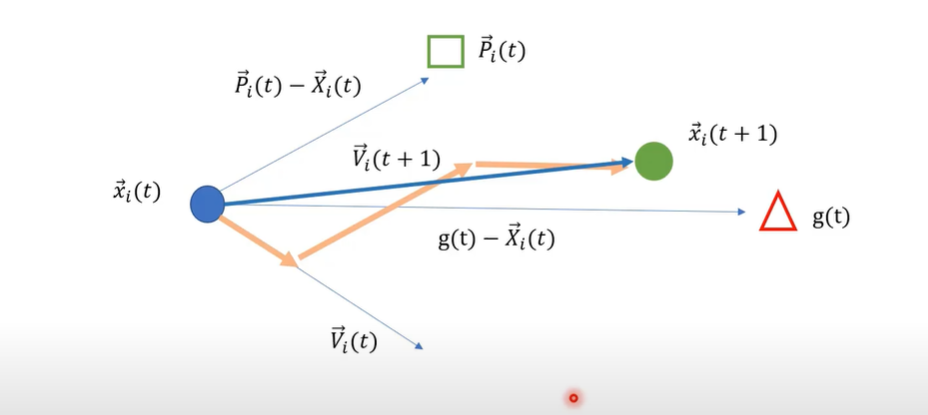


$$x_{i\;} \left(t+1\right)=x\left(t\right)+V_i \left(t+1\right)$$



$$\begin{array}{l}
V_i \left(t+1\right)=W\;v_i \left(t\right)+c_1 \left(P_i -x_i \left(t\right)\right)+c_{2\;} \left(g\left(t\right)-x_i \left(t\right)\right)\\
W=\mathrm{Coef}\;\mathrm{de}\;\mathrm{Valor}\;\mathrm{Real}
\end{array}$$



$$\begin{array}{l}
{\vec{V} }_{\mathrm{ij}} \left(t+1\right)=W\;V_i \left(t\right)\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\mathrm{Termino}\;\mathrm{de}\;\mathrm{inercia}\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;+r_1 *C_1 \;\left(P_i \left(t\right)-x_i \left(t\right)\right)\;\;\forall \;r_1 \;\left\lbrack 0,1\right\rbrack \;\;\;\;\;\;\;\mathrm{Componente}\;\mathrm{Cognitivo}\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;+r_2 *C_2 \;\left(g\left(t\right)-x_i \left(t\right)\right)\;\;\;\forall \;r_2 \;\left\lbrack 0,1\right\rbrack \;\;\;\;\;\;\;\mathrm{Componente}\;\mathrm{Social}\;\;\;
\end{array}$$



$$x_{\mathrm{ij}} \left(t+1\right)=x_{\mathrm{ij}} \left(t\right)+V_{\mathrm{ij}} \left(t+1\right)$$


clc
clear


## Definicion del problema

costFunction = @(x) fun(x); % funcion de Costo
nVar = 5;                   % Numero de variables de Descision
varSize = [1 nVar];         % Matriz Variables de Descision
varMin  = -10;              % limite Inferior
varMax  = 10;               % Limite Superior

## Parametros de PSO

maxIt = 100;                % Numero maximo de Iteraciones
nPop  = 50;                 % Tamaño del enjambre
w     = 1;                  % Coef de Inercia
c1    = 2;                  % coef de aceleracion personal
c2    = 2;                  % coef de aceleracion Social

## Particulas

empty_particle.Position      = [];
empty_particle.Velocity      = [];
empty_particle.Cost          = [];
empty_particle.Best.Position = [];
empty_particle.Best.Cost     = [];


## Matriz de Poblacion

particle = repmat(empty_particle,nPop,1);


## inicializar la base Global

globalBest.Cost = inf;

## Inicializar Miembros

for i=1:nPop
    particle(i).Position        = unifrnd(varMin, varMax, varSize);
    particle(i).Velocity        = zeros(varSize);
    particle(i).Cost            = costFunction(particle(i).Position);
    particle(i).Best.Position   = particle(i).Position;
    particle(i).Best.Cost       = particle(i).Cost;

    if particle(i).Best.Cost < globalBest.Cost
        globalBest = particle(i).Best
    end
end

globalBest = struct with fields:
    Position: [8.7663 -4.8915 0.6633 9.0951 -4.6450]
        Cost: 205.5118


globalBest = struct with fields:
    Position: [-4.9983 8.5535 -8.6284 -4.0120 1.8317]
        Cost: 192.0442


globalBest = struct with fields:
    Position: [-5.9340 2.7177 5.9674 0.0340 3.0162]
        Cost: 87.3071


globalBest = struct with fields:
    Position: [-4.0529 -2.0716 -1.5849 -3.7705 3.8769]
        Cost: 52.4763


globalBest = struct with fields:
    Position: [0.5487 4.4998 2.1483 1.7673 -1.3313]
        Cost: 30.0607



bestCosts = zeros(maxIt,1);


## Bucle principal PSO

for it=1:maxIt
    for i=1:nPop
        particle(i).Velocity = w*particle(i).Velocity ...
                             + c1*rand(varSize).*(particle(i).Best.Position - particle(i).Position)...
                             + c2*rand(varSize).*(globalBest.Position - particle(i).Position);

        particle(i).Position = particle.Position + particle(i).Velocity; 
        particle(i).Cost     = costFunction(particle(i).Position);

        if particle(i).Cost < particle(i).Best.Cost
            particle(i).Best.Position = particle(i).Position;
            particle(i).Best.Cost     = particle(i).Cost;
            
            if particle(i).Best.Cost < globalBest.Cost
                globalBest = particle(i).Best
            end
        end
    end
end

Error using  + 
Too many input arguments.